# SC42025 Filtering & Identification

## MATLAB EXERCISE HW2

We want to localize a vehicle with GPS data. However the data is noisy and we cannot accurately estimate the state of the vehicle relying merely on the GPS signal. In order to improve the estimate, we wish to combine the data with vehicle acceleration measurements from an accelerometer mounted on the vehicle.


$$\mathit{\mathbf{x}}={\left\lbrack \begin{array}{cc}
{\mathit{\mathbf{p}}}^{\mathrm{T}}  & {\mathit{\mathbf{v}}}^{\mathrm{T}} 
\end{array}\right\rbrack }^{\mathrm{T}}$$


Where $\mathit{\mathbf{p}}={\left\lbrack \begin{array}{cc}
p_x  & p_y 
\end{array}\right\rbrack }^{\mathrm{T}}$ and $\mathit{\mathbf{v}}={\left\lbrack \begin{array}{cc}
v_x  & v_y 
\end{array}\right\rbrack }^{\mathrm{T}}$ are the vector position and velocity in the ground plane respectively. The equations of motion are


$${\mathit{\mathbf{p}}}_k ={\mathit{\mathbf{p}}}_{k-1} +{\mathit{\mathbf{v}}}_{k-1} \Delta t+\frac{1}{2}{\mathit{\mathbf{a}}}_{k-1} \Delta t^2$$



$${\mathit{\mathbf{v}}}_k ={\mathit{\mathbf{v}}}_{k-1} +{\mathit{\mathbf{a}}}_{k-1} \Delta t$$


Where ${\mathit{\mathbf{a}}}_k$ is the acceleration vector at time step k. It is determined using the measured acceleration $\tilde{\mathit{\mathbf{a}}}$ from the accelerometer as


$$\mathbf{\textit{a}}_k = \mathbf{\tilde{\textit{a}}}_k + \epsilon_k \qquad \epsilon_k \sim \mathcal{N}(0, \sigma_e^2I_{2\times2})$$


The accelerometer compensates for the acceleration due to gravity, and therefore only the vehicle accelerations are recorded.

At each time step we also have available measured GPS state information as


$$\mathbf{\textit{z}}_k =\left[\matrix{ \mathbf{\textit{p}}_k  \cr \mathbf{\textit{v}}_k  } \right] + \eta_k \qquad \eta_k \sim \mathcal{N}(0, R)$$


It is given that $\sigma_e =0\ldotp 3\;{\textrm{ms}}^{-2}$ and $R=\textrm{diag}\left(3^2 ,3^2 ,0\ldotp {03}^2 ,0\ldotp {03}^2 \right)$. The timestep $\Delta t=0\ldotp 1\mathrm{s}$, and the total time-period of the trial is 10s. The vehicle is at the origin with zero velocity at the beginning of the trial. Also important to note here is that all the measurements are already in the global coordinate system, so no coordinate transformations are required.

Using the given equations, model a state space equation of the form


$$      \mathbf{\textit{x}}_{k+1} = A\mathbf{\textit{x}}_{k} + B\tilde{\mathbf{\textit{a}}}_k + w_k  \qquad w_k \sim \mathcal{N}(0,Q)\\
       \mathbf{\textit{z}}_k = C\mathbf{\textit{x}}_{k} + \eta_k \qquad \eta_k \sim \mathcal{N}(0, R)$$


Note that in the above state space model, the measured accelerations are used as an input to the system, while the GPS measurements are considered as the outputs. 

What are the matrices $A,B,C\;\textrm{and}\;Q$ ?

$A=\left\lbrack \begin{array}{cccc}
1 & 0 & \Delta t & 0\\
0 & 1 & 0 & \Delta t\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$, $B=\left\lbrack \begin{array}{cc}
\frac{1}{2}\Delta t^2  & 0\\
0 & \frac{1}{2}\Delta t^2 \\
\Delta t & 0\\
0 & \Delta t
\end{array}\right\rbrack$, $C=I_{4\times 4}$, $Q=\sigma_e^2 \left\lbrack \begin{array}{cccc}
\frac{1}{4}\Delta t^4  & 0 & \frac{1}{2}\Delta t^3  & 0\\
0 & \frac{1}{4}\Delta t^4  & 0 & \frac{1}{2}\Delta t^3 \\
\frac{1}{2}\Delta t^3  & 0 & \Delta t^2  & 0\\
0 & \frac{1}{2}\Delta t^3  & 0 & \Delta t^2 
\end{array}\right\rbrack$

Import the data from the file *data_hw2.mat* file. It contains the noisy accelerometer readings (${\tilde{\mathit{\mathbf{a}}} }_k$), and the GPS state measurements(${\mathit{\mathbf{z}}}_k$). Using the acceleration measurements simulate the state space model. 

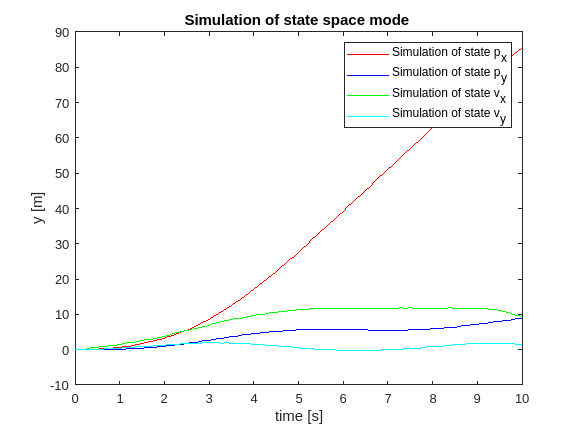

clear;
dt = 0.1;                           % timestep
t = 0:0.1:10;                       % simulation time
T = length(t);                      % total simulation time
x0 = zeros(4,1);                    % initial state
load("data_hw2.mat")                     % load data
R=[9 0 0 0;0 9 0 0;0 0 0.0009 0; 0 0 0 0.0009;];
A=[1 0 dt 0;0 1 0 dt; 0 0 1 0; 0 0 0 1];
B=[0.5*dt^2 0; 0 0.5*dt^2; dt 0; 0 dt];
C=eye(4,4);
D=0;
Q=0.3^2.*[dt^4/4 0 dt^3/2 0; 0 dt^4/4 0 dt^3/2;dt^3/2 0 dt^2 0;0 dt^3/2 0 dt^2];
epsilon=[0.09 0;0 0.09];
u=a_meas;
sys = ss(A,B,C,D,dt);
y1=lsim(sys,u,t,x0);
figure
plot(t,y1(:,1),'r-');
hold on
plot(t,y1(:,2),'b-');
hold on
plot(t,y1(:,3),'g-');
hold on
plot(t,y1(:,4),'c-');
xlabel('time [s]');ylabel('y [m]');title('Simulation of state space model');
legend('Simulation of state p_x','Simulation of state p_y','Simulation of state v_x','Simulation of state v_y');

*Hint: You can use the function lsim() for simulating the state space model*.

From the GPS data, plot the measured position (in the 2D plane) and the vehicle speed.

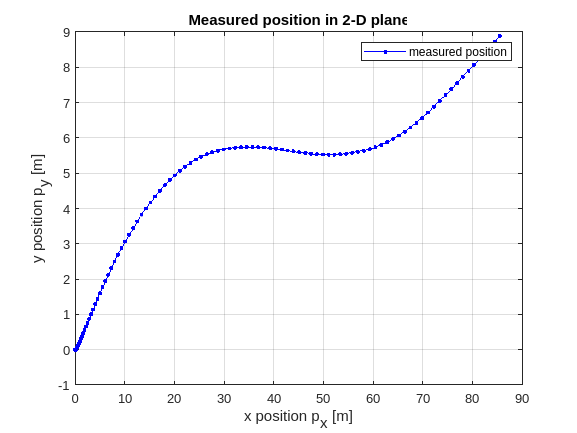

figure
plot(y1(:,1),y1(:,2),'b.-',y1(:,1),y1(:,2),'b.-');grid on;
xlabel('x position p_x [m]');ylabel('y position p_y [m]');
hold on
title('Measured position in 2-D plane');
legend('measured position');

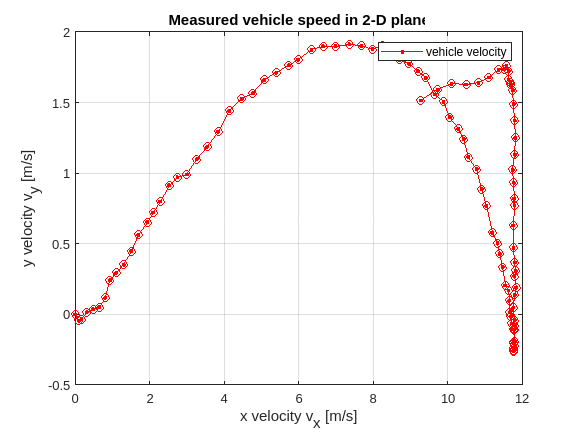

figure
plot(y1(:,3),y1(:,4),'r.-',y1(:,3),y1(:,4),'ro');grid on;
xlabel('x velocity v_x [m/s]');ylabel('y velocity v_y [m/s]');
title('Measured vehicle speed in 2-D plane');
legend('vehicle velocity');

Construct an asymptotic Luenberger observer such that the poles of the observer model are placed at *diag(0.95, 0.95, 0.9, 0.9) *i.e. construct a system of the form


$${\hat{\mathit{\mathbf{x}}} }_{k+1} =\left(A-\textrm{KC}\right){\hat{\mathit{\mathbf{x}}} }_k +B{\tilde{\mathit{\mathbf{a}}} }_k +K{\mathit{\mathbf{z}}}_{\textrm{meas},\;k}$$



$${\hat{\mathit{\mathbf{z}}} }_k =C{\hat{\mathit{\mathbf{x}}} }_k$$


Simulate the system using the acceleration measurements(${\tilde{\mathit{\mathbf{a}}} }_k$) and the GPS readings (${\mathit{\mathbf{z}}}_{\textrm{meas}}$). 

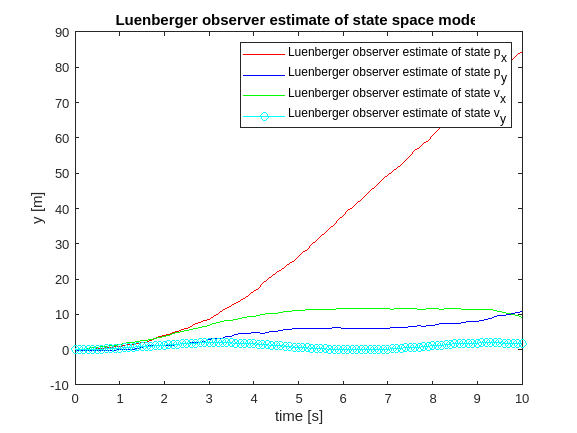

% Design an observer to estimate state of vehicle using both acceleration
% and GPS measurements
p=[0.95 0.95 0.9 0.9];
K = place(A',C',p)';
u_new=B*a_meas+K*z_meas';
A_new=A-K*C;
B_new=eye(4,4);
sys = ss(A_new,B_new,C,D,dt);
y2=lsim(sys,u_new,t,x0);
figure
plot(t,y2(:,1),'r-');
hold on
plot(t,y2(:,2),'b-');
hold on
plot(t,y2(:,3),'g-');
hold on
plot(t,y2(:,4),'co-');
xlabel('time [s]');ylabel('y [m]');title('Luenberger observer estimate of state space model');
legend('Luenberger observer estimate of state p_x','Luenberger observer estimate of state p_y','Luenberger observer estimate of state v_x','Luenberger observer estimate of state v_y');

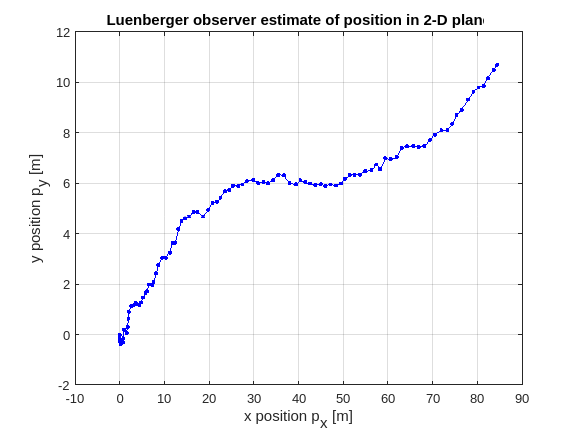

figure
plot(y2(:,1),y2(:,2),'b-',y2(:,1),y2(:,2),'b.');grid on;
hold on
xlabel('x position p_x [m]');ylabel('y position p_y [m]');
title('Luenberger observer estimate of position in 2-D plane');

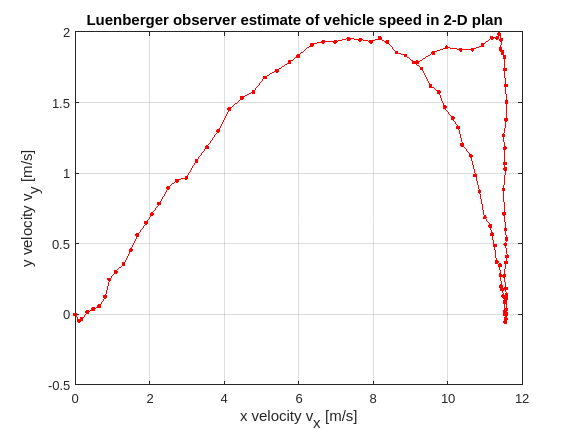

figure
plot(y2(:,3),y2(:,4),'r-',y2(:,3),y2(:,4),'r.');grid on;
hold on
xlabel('x velocity v_x [m/s]');ylabel('y velocity v_y [m/s]');
title('Luenberger observer estimate of vehicle speed in 2-D plane');

*Hint: You can use the command K = place(A',C',p)' to find K for the given poles.*

Construct a Kalman Filter to estimate the state of the given state space model, using the same data as done in the previous section. No use of MATLAB toolboxes is allowed, you need to implement the Kalman Filter by yourself. Use the matrix $Q$ you found in the  first question, and the matrix $R$ as given.

%%Kalman filter algorithm
xmean=x0;%initial mean
xcor=0;%initial covariance
x_estimate=zeros(4,102);
x_estimate(:,1)=x0;
for i=1:length(t)
%measurement update
K_update=xcor*C'*inv(C*xcor*C'+R)*C*xcor;
xmean_update=xmean+K_update*(z_meas(i,:)'-C*xmean);
xcor_update=xcor-xcor*C'*inv(C*xcor*C'+R)*C*xcor;
%time update
xmean=A*xmean_update+B*u(:,i);
x_estimate(:,i+1)=xmean;
xcor=A*xcor_update*A'+Q;
end

Load the file *ground_truth_hw2.mat. *This file contains the actual states of the vehicle. Plot the true position in the 2D plane, along with the simulated state, Luenberger observer estimate, and Kalman Filter estimate in a graph. In another figure, plot the magnitude of the true vehicle velocity, with the simulated velocity, Luenberger observer estimate, and Kalman Filter estimate. Make certain to provide clear titles, axis labels and legends.

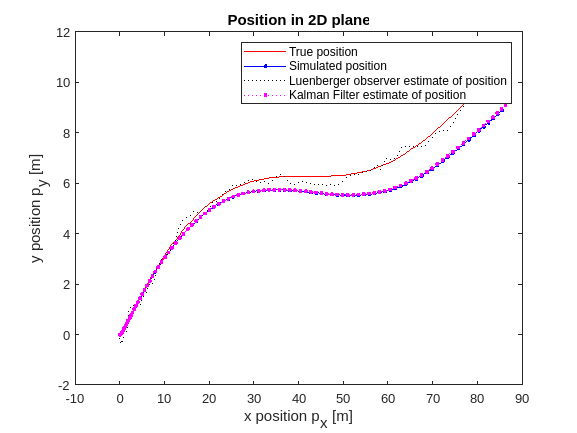

load("ground_truth_hw2.mat") % load true state data
%postion
figure
plot(z_true(:,1),z_true(:,2),'r-');
hold on
plot(y1(:,1),y1(:,2),'b.-');
hold on
plot(y2(:,1),y2(:,2),'k:');
hold on
plot(x_estimate(1,:),x_estimate(2,:),'m:.');
xlabel('x position p_x [m]');ylabel('y position p_y [m]');title('Position in 2D plane');
legend('True position','Simulated position','Luenberger observer estimate of position','Kalman Filter estimate of position');

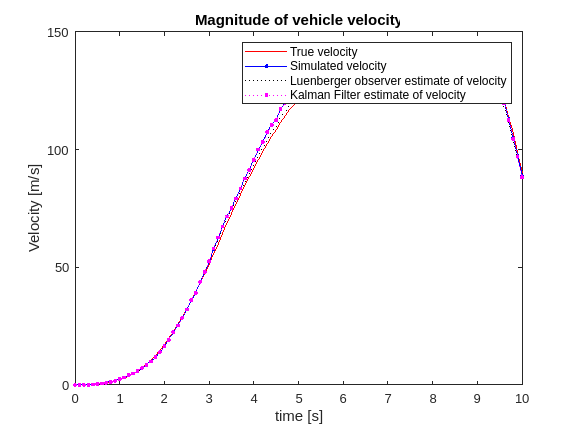

%magnitude of vehicle velocity
v_true=z_true(:,3).*z_true(:,3)+z_true(:,4).*z_true(:,4);
v_simulation=y1(:,3).*y1(:,3)+y1(:,4).*y1(:,4);
v_luenberger=y2(:,3).*y2(:,3)+y2(:,4).*y2(:,4);
v_kalman=x_estimate(3,1:101).*x_estimate(3,1:101)+x_estimate(4,1:101).*x_estimate(4,1:101);
figure
plot(t,v_true,'r-');
hold on
plot(t,v_simulation,'b.-');
hold on
plot(t,v_luenberger,'k:');
hold on
plot(t,v_kalman,'m:.');
xlabel('time [s]');ylabel('Velocity [m/s]');title('Magnitude of vehicle velocity');
legend('True velocity','Simulated velocity','Luenberger observer estimate of velocity','Kalman Filter estimate of velocity');

 Finally calculate and plot the difference between the magnitude of estimated velocity and the magnitude of the true velocity for the simulation, the Luenberger observer, and the Kalman Filter.

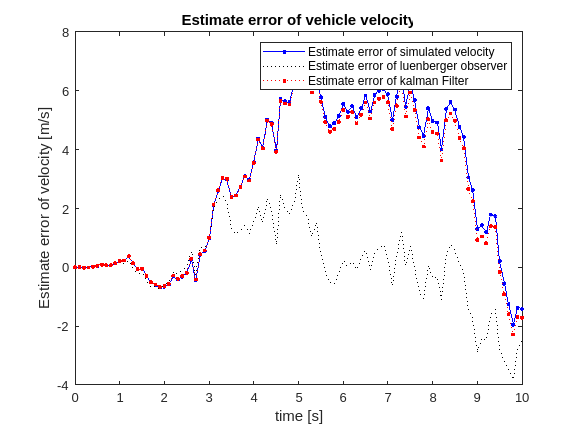

%estimate error of vehicle velocity
v_true=z_true(:,3).*z_true(:,3)+z_true(:,4).*z_true(:,4);
v_simulation_error=v_simulation-v_true;
v_luenberger_error=v_luenberger-v_true;
v_kalman_error=v_kalman'-v_true;
figure
plot(t,v_simulation_error,'b.-');
hold on
plot(t,v_luenberger_error,'k:');
hold on
plot(t,v_kalman_error,'r:.');
xlabel('time [s]');ylabel('Estimate error of velocity [m/s]');title('Estimate error of vehicle velocity');
legend('Estimate error of simulated velocity','Estimate error of luenberger observer','Estimate error of kalman Filter');